clc;
clear all;
close all;
% Read the .wav file
[x, fs] = audioread("out.wav");

% Digital filter specifications
Sampling_frequency = fs

Sampling_frequency = 44100

Transition_band = 900

Transition_band = 900

Fp = 3 * 10^3

Fp = 3000

Ks = 74

Ks = 74

Fs = 3.9 * 10^3

Fs = 3900

Sampling_time = 1 / Sampling_frequency

Sampling_time = 2.2676e-05

Omega_p = 2 * pi * Fp

Omega_p = 1.8850e+04

Omega_s = 2 * pi * (Fp + Transition_band)

Omega_s = 2.4504e+04


% Converting the analog filter specifications into digital specifications
Wp = Omega_p * Sampling_time

Wp = 0.4274

Ws = Omega_s * Sampling_time

Ws = 0.5557


% The filter should provide minimum 74 dB attenuation in the stop band
k = 6 % k value for blackmann

k = 6

N = (8 * pi) / (Ws - Wp);
N = ceil(N)

N = 196

if (mod(N,2)==0)
  Alpha = N / 2
else
  Alpha = (N - 1) / 2
end

Alpha = 98


% Cutoff frequency
Wc2 = Wp + ((Ws - Wp) / 2)

Wc2 = 0.4915

Wc1=300*2*pi/fs

Wc1 = 0.0427

% Impulse response of the FIR lowpass filter using the Blackman window
n=0:N-1

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


WHam = 0.42 - 0.5 * cos(2 * pi * (0:N-1) / (N-1)) + 0.08 * cos(4 * pi * (0:N-1) / (N-1)) 

WHam =    -0.0000    0.0001    0.0004    0.0008    0.0015    0.0024    0.0034    0.0047    0.0061    0.0078    0.0097    0.0118    0.0142    0.0168    0.0196    0.0227    0.0261    0.0298    0.0337    0.0380    0.0425    0.0474    0.0526    0.0582    0.0641    0.0704    0.0771    0.0841    0.0915    0.0994    0.1076    0.1162    0.1253    0.1348    0.1447    0.1551    0.1658    0.1770    0.1887    0.2008    0.2133    0.2262    0.2396    0.2533    0.2675    0.2821    0.2970    0.3123    0.3280    0.3440


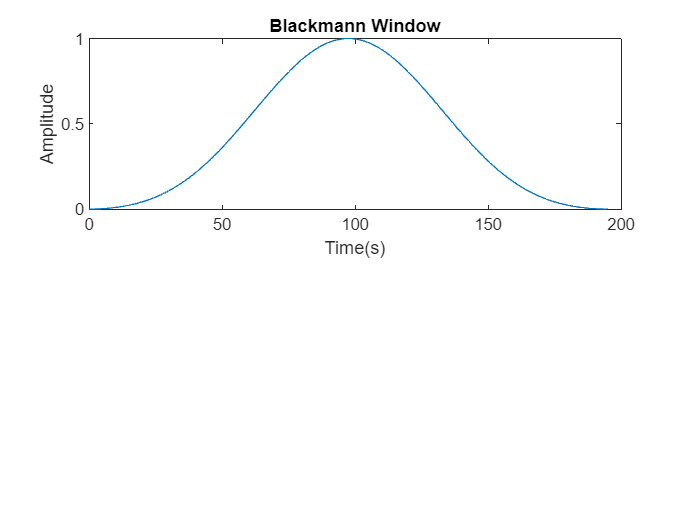


h_blackman = ideal_bp_filter(Wc1, Wc2, N) .* WHam;
figure;
subplot(2,1,1);
plot(n, WHam);
title('Blackmann Window');
xlabel('Time(s)');
ylabel('Amplitude');

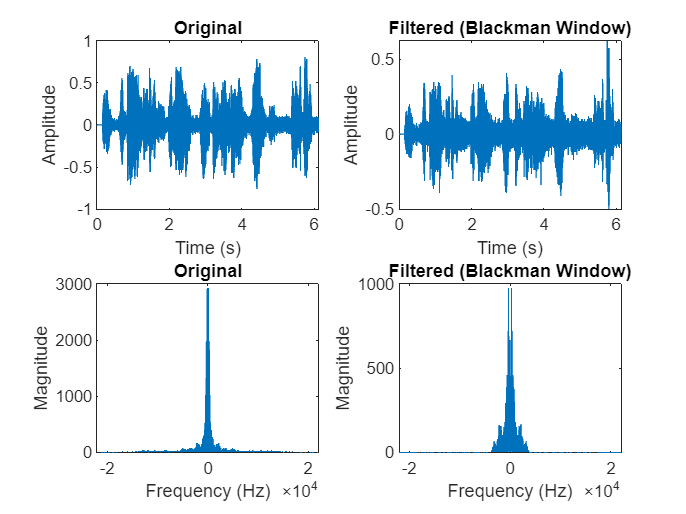

res = conv(x, h_blackman);

subplot(2,2,1);
t = (0:length(x)-1) / fs;
plot(t, x);
title('Original');
xlabel('Time (s)');
ylabel('Amplitude');
t = (0:length(res)-1) / Sampling_frequency; % Time vector

subplot(2,2,2);
plot(t, res);
title('Filtered (Blackman Window)');
xlabel('Time (s)');
ylabel('Amplitude');

n = length(x);  % Set n based on the length of the signal
y = fft(x, n);
m = abs(y);
f = (0:length(y)-1) * fs / length(y);
Y = fftshift(m);
fshift = (-n/2:n/2-1) * (fs/n);

% Filtered
nf = length(res);  % Set n based on the length of the signal
yf = fft(res, nf);
mf = abs(yf);
ff = (0:length(yf)-1) * Sampling_frequency / length(yf);
Yf = fftshift(mf);
fshiftf = (-nf/2:nf/2-1) * (Sampling_frequency/nf);

subplot(2,2,3);
plot(fshift, Y);
title('Original');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(2,2,4);
plot(fshiftf, Yf);
title('Filtered (Blackman Window)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

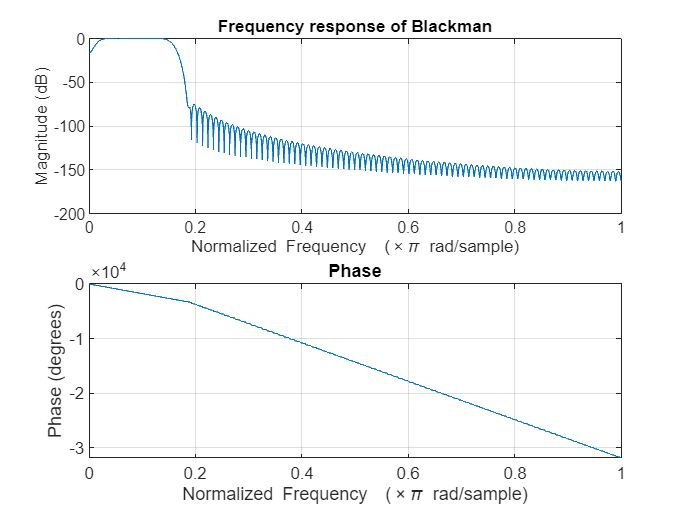


% Ideal lowpass filter function
figure
freqz(h_blackman, 1, Sampling_frequency);
title('Frequency response of Blackman');

function hd = ideal_bp_filter(wc1, wc2, N)
    % Ideal bandpass filter function
    % wc1: Lower cutoff frequency
    % wc2: Upper cutoff frequency
    % N: Filter order
    n = 0:N-1;
    hd = (wc2 / pi) * sinc(wc2 * (n - (N / 2)) / pi) - (wc1 / pi) * sinc(wc1 * (n - (N / 2)) / pi);
end
